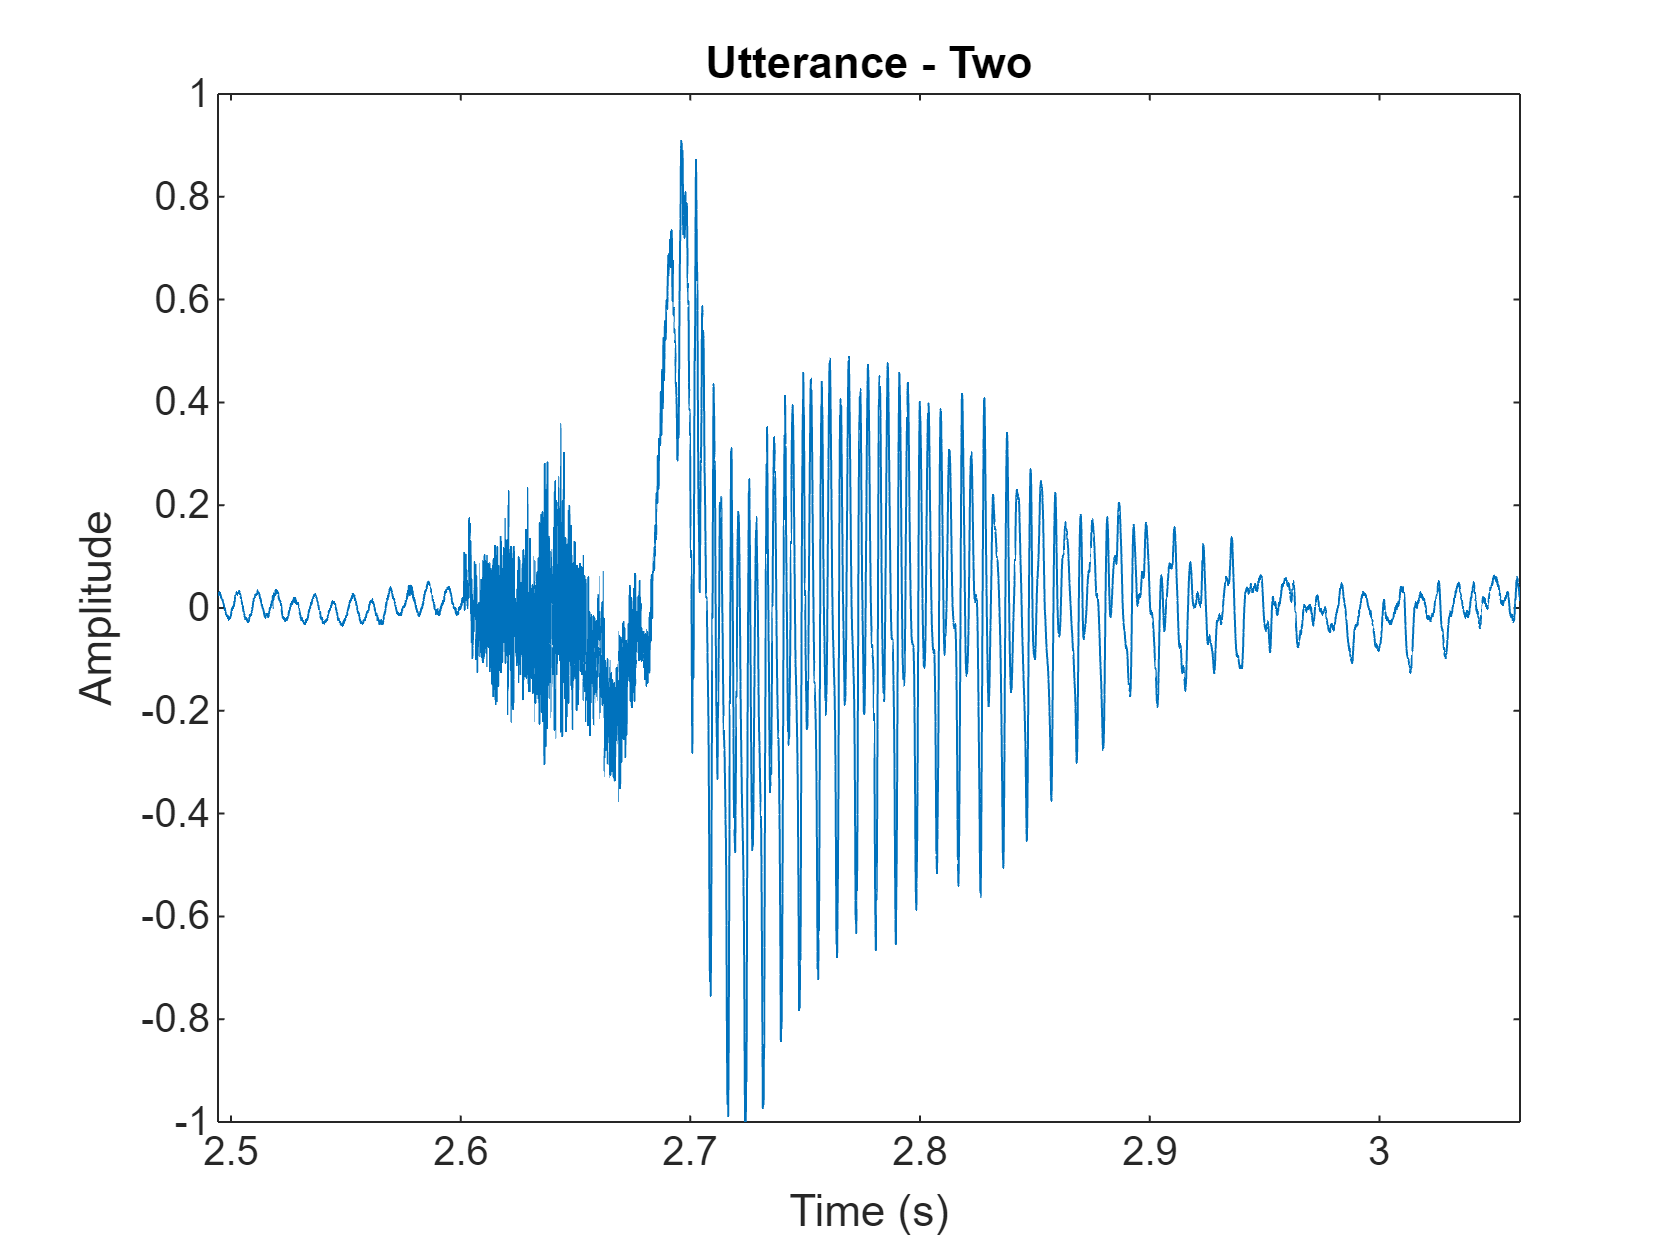

[audioIn,fs] = audioread("Counting-16-44p1-mono-15secs.wav");
twoStart = 110e3;
twoStop = 135e3;
audioIn = audioIn(twoStart:twoStop);
timeVector = linspace(twoStart/fs,twoStop/fs,numel(audioIn));

sound(audioIn,fs)

figure
plot(timeVector,audioIn)
axis([(twoStart/fs) (twoStop/fs) -1 1])
ylabel("Amplitude")
xlabel("Time (s)")
title("Utterance - Two")

Este ejemplo utiliza una ventana de 30 ms con una superposición de 25 ms. Utilice la función de tono para ver cómo cambia el tono con el tiempo.

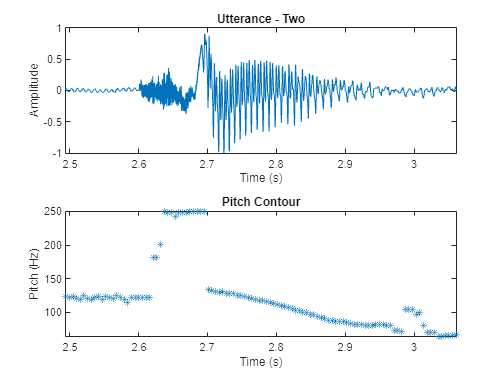

windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);

f0 = pitch(audioIn,fs,WindowLength=windowLength,OverlapLength=overlapLength,Range=[50,250]);

figure
tiledlayout(2,1)

nexttile()
plot(timeVector,audioIn)
axis([(110e3/fs) (135e3/fs) -1 1])
ylabel("Amplitude")
xlabel("Time (s)")
title("Utterance - Two")

nexttile()
timeVectorPitch = linspace(twoStart/fs,twoStop/fs,numel(f0));
plot(timeVectorPitch,f0,"*")
axis([(110e3/fs) (135e3/fs) min(f0) max(f0)])
ylabel("Pitch (Hz)")
xlabel("Time (s)")
title("Pitch Contour")

energyThreshold = 20;
[segments,~] = buffer(audioIn,windowLength,overlapLength,"nodelay");
ste = sum((segments.*hamming(windowLength,"periodic")).^2,1);
isSpeech = ste(:) > energyThreshold;

The simplest method to distinguish between voiced and unvoiced speech is to analyze the zero crossing rate. A large number of zero crossings implies that there is no dominant low-frequency oscillation. If the zero crossing rate for a frame is below a given threshold, you declare it as voiced.

zcrThreshold = 0.02;
zcr = zerocrossrate(audioIn,WindowLength=windowLength,OverlapLength=overlapLength);
isVoiced = zcr < zcrThreshold;

Combine `isSpeech` and `isVoiced` to determine whether a frame contains voiced speech.

voicedSpeech = isSpeech & isVoiced;

Remove regions that do not correspond to voiced speech from the pitch estimate and plot.

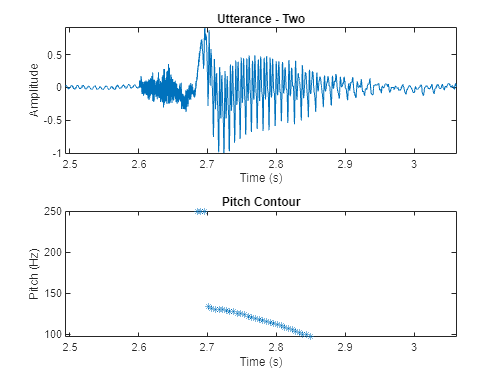

f0(~voicedSpeech) = NaN;

figure
tiledlayout(2,1)

nexttile()
plot(timeVector,audioIn)
axis([(110e3/fs) (135e3/fs) -1 1])
axis tight
ylabel("Amplitude")
xlabel("Time (s)")
title("Utterance - Two")

nexttile()
plot(timeVectorPitch,f0,"*")
axis([(110e3/fs) (135e3/fs) min(f0) max(f0)])
ylabel("Pitch (Hz)")
xlabel("Time (s)")
title("Pitch Contour")

**Mel-Frequency Cepstrum Coefficients (MFCC)**

MFCC are popular features extracted from speech signals for use in recognition tasks. In the source-filter model of speech, MFCC are understood to represent the filter (vocal tract). The frequency response of the vocal tract is relatively smooth, whereas the source of voiced speech can be modeled as an impulse train. The result is that the vocal tract can be estimated by the spectral envelope of a speech segment.

The motivating idea of MFCC is to compress information about the vocal tract (smoothed spectrum) into a small number of coefficients based on an understanding of the cochlea.

Although there is no hard standard for calculating MFCC, the basic steps are outlined by the diagram.

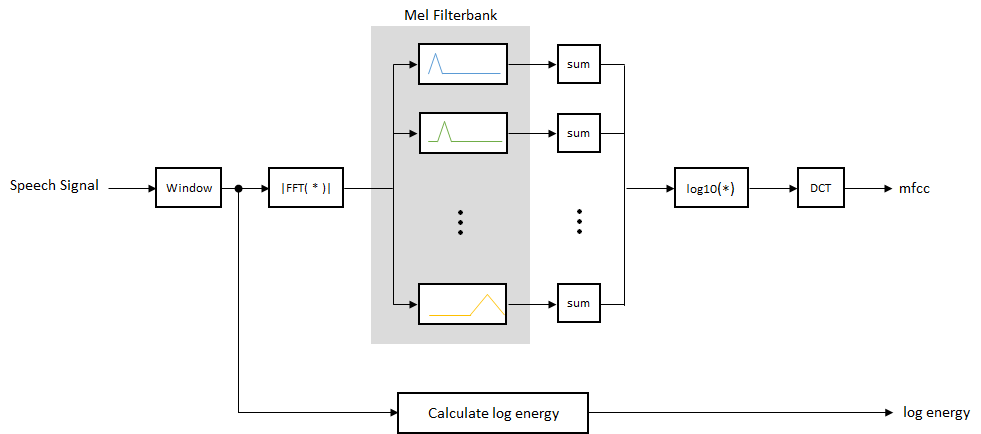

The mel filterbank linearly spaces the first 10 triangular filters and logarithmically spaces the remaining filters. The individual bands are weighted for even energy. The graph represents a typical mel filterbank.

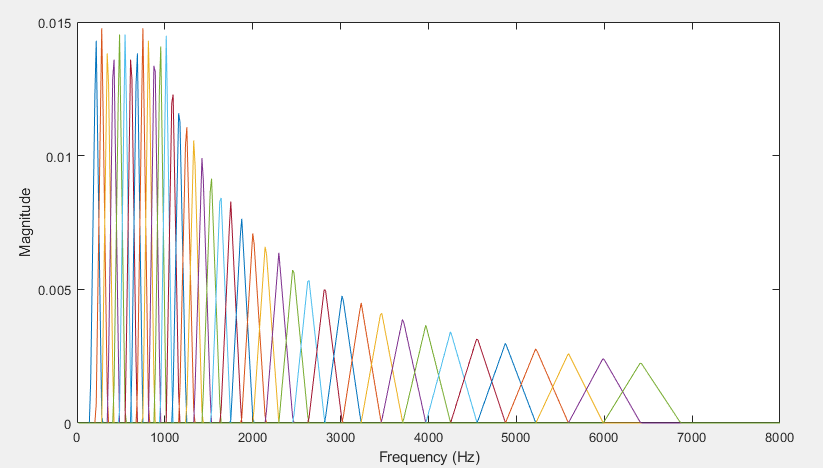

This example uses [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) to calculate the MFCC for every file.

## Data Set

This example uses a subset of the Common Voice data set from Mozilla [1]. The data set contains 48 kHz recordings of subjects speaking short sentences. The helper function in this section organizes the downloaded data and returns an [`audioDatastore`](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) object. The data set uses 1.36 GB of memory.

Download the data set if it doesn't already exist and unzip it into `tempdir`.

downloadFolder = matlab.internal.examples.downloadSupportFile("audio","commonvoice.zip");
dataFolder = tempdir;
if ~datasetExists(string(dataFolder) + "commonvoice")
    unzip(downloadFolder,dataFolder);
end

Extract the speech files for 10 speakers (5 female and 5 male) and place them into an [`audioDatastore`](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) using the `commonVoiceHelper` function. The datastore enables you to collect necessary files of a file format and read them. The function is placed in your current folder when you open this example.

ads = commonVoiceHelper

ads =   audioDatastore with properties:

                       Files: {
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116626.wav';
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116631.wav';
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116643.wav'
                               ... and 172 more
                              }
                     Folders: {
                              'C:\Users\bhemmat\AppData\Local\Temp\commonvoice\train\clips'
                              }
                      Labels: [3; 3; 3 ... and 172 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


The [`splitEachLabel`](docid:audio_ref#mw_8757c90d-c18a-4d74-88c6-45c3903e8f3e) function of `audioDatastore` splits the datastore into two or more datastores. The resulting datastores have the specified proportion of the audio files from each label. In this example, the datastore is split into two parts. 80% of the data for each label is used for training, and the remaining 20% is used for testing. The [`countEachLabel`](docid:audio_ref#mw_27293e0c-5066-45c4-b34d-e2814c56921f) function of `audioDatastore` is used to count the number of audio files per label. In this example, the label identifies the speaker.

[adsTrain,adsTest] = splitEachLabel(ads,0.8);

Display the datastore and the number of speakers in the train datastore.

adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116626.wav';
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116631.wav';
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116643.wav'
                               ... and 136 more
                              }
                     Folders: {
                              'C:\Users\bhemmat\AppData\Local\Temp\commonvoice\train\clips'
                              }
                      Labels: [3; 3; 3 ... and 136 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 10×2 table
    Label    Count
    _____    _____

     1        14  
     10       12  
     2        12  
     3        18  
     4        14  
     5        16  
     6        17  
     7        11  
     8        11  
     9        14  


Display the datastore and the number of speakers in the test datastore.

adsTest

adsTest =   audioDatastore with properties:

                       Files: {
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116761.wav';
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116762.wav';
                              ' ...\AppData\Local\Temp\commonvoice\train\clips\common_voice_en_116769.wav'
                               ... and 33 more
                              }
                     Folders: {
                              'C:\Users\bhemmat\AppData\Local\Temp\commonvoice\train\clips'
                              }
                      Labels: [3; 3; 3 ... and 33 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 10×2 table
    Label    Count
    _____    _____

     1         4  
     10        3  
     2         3  
     3         4  
     4         4  
     5         4  
     6         4  
     7         3  
     8         3  
     9         4  


To preview the content of your datastore, read a sample file and play it using your default audio device.

[sampleTrain,dsInfo] = read(adsTrain);
sound(sampleTrain,dsInfo.SampleRate)

Reading from the train datastore pushes the read pointer so that you can iterate through the database. Reset the train datastore to return the read pointer to the start for the following feature extraction.

reset(adsTrain)

## Feature Extraction

Extract pitch and MFCC features from each frame that corresponds to voiced speech in the training datastore. Audio Toolbox™ provides `audioFeatureExtractor` so that you can quickly and efficiently extract multiple features. Configure an [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) to extract pitch, short-time energy, zcr, and MFCC.

fs = dsInfo.SampleRate;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"),OverlapLength=overlapLength, ...
    zerocrossrate=true,shortTimeEnergy=true,pitch=true,mfcc=true);

When you call the extract function of `audioFeatureExtractor`, all features are concatenated and returned in a matrix. You can use the info function to determine which columns of the matrix correspond to which features.

featureMap = info(afe)

featureMap = struct with fields:
               mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]
              pitch: 14
      zerocrossrate: 15
    shortTimeEnergy: 16


Extract features from the data set.

features = [];
labels = [];
energyThreshold = 0.005;
zcrThreshold = 0.2;

allFeatures = extract(afe,adsTrain);
allLabels = adsTrain.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    label = repelem(allLabels(ii),size(thisFeature,1));
    
    features = [features;thisFeature];
    labels = [labels,label];
end

Pitch and MFCC are not on the same scale. This will bias the classifier. Normalize the features by subtracting the mean and dividing the standard deviation.

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

## Train Classifier

Now that you have collected features for all 10 speakers, you can train a classifier based on them. In this example, you use a K-nearest neighbor (KNN) classifier. KNN is a classification technique naturally suited for multiclass classification. The hyperparameters for the nearest neighbor classifier include the number of nearest neighbors, the distance metric used to compute distance to the neighbors, and the weight of the distance metric. The hyperparameters are selected to optimize validation accuracy and performance on the test set. In this example, the number of neighbors is set to 5 and the metric for distance chosen is squared-inverse weighted Euclidean distance. For more information about the classifier, refer to [`fitcknn`](docid:stats_ug#bt6cr9l).

Train the classifier and print the cross-validation accuracy. [`crossval`](docid:stats_ug#mw_f146c8ce-56ce-4f92-82c6-b22ad9bb0376) and [`kfoldloss`](docid:stats_ug#bsu1r2a-1) are used to compute the cross-validation accuracy for the KNN classifier.

Specify all the classifier options and train the classifier.

trainedClassifier = fitcknn(features,labels, ...
    Distance="euclidean", ...
    NumNeighbors=5, ...
    DistanceWeight="squaredinverse", ...
    Standardize=false, ...
    ClassNames=unique(labels));

Perform cross-validation.

k = 5;
group = labels;
c = cvpartition(group,KFold=k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,CVPartition=c);

Compute the validation accuracy.

validationAccuracy = 1 - kfoldLoss(partitionedModel,LossFun="ClassifError");
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 97.05%


Visualize the confusion chart.

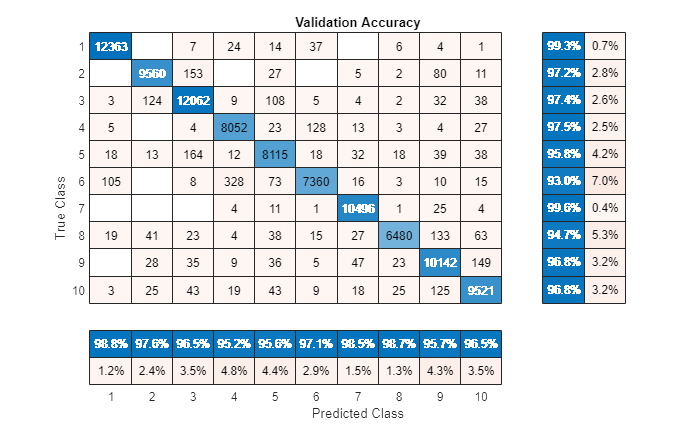

validationPredictions = kfoldPredict(partitionedModel);
figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels,validationPredictions,title="Validation Accuracy", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

You can also use the [`Classification Learner`](docid:stats_ug#buggk6h) app to try out and compare various classifiers with your table of features.

## Test Classifier

In this section, you test the trained KNN classifier with speech signals from each of the 10 speakers to see how well it behaves with signals that were not used to train it. 

Read files, extract features from the test set, and normalize them.

features = [];
labels = [];
numVectorsPerFile = [];

allFeatures = extract(afe,adsTest);
allLabels = adsTest.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    numVec = size(thisFeature,1);
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    
    label = repelem(allLabels(ii),numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;thisFeature];
    labels = [labels,label];
end
features = (features-M)./S;

Predict the label (speaker) for each frame by calling `predict` on `trainedClassifier`.

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

Visualize the confusion chart.

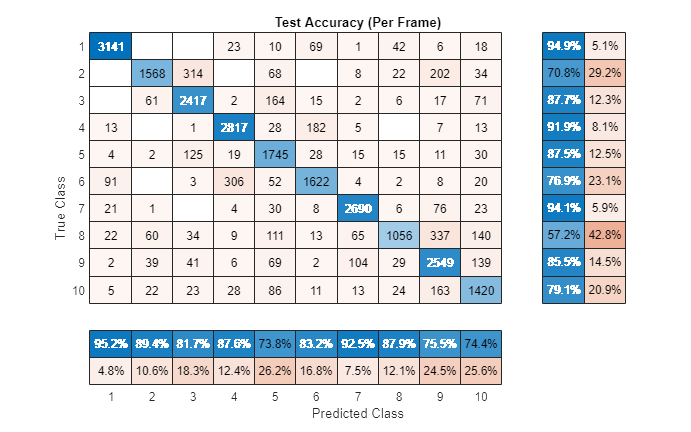

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels(:),prediction,title="Test Accuracy (Per Frame)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

For a given file, predictions are made for every frame. Determine the mode of predictions for each file and then plot the confusion chart.

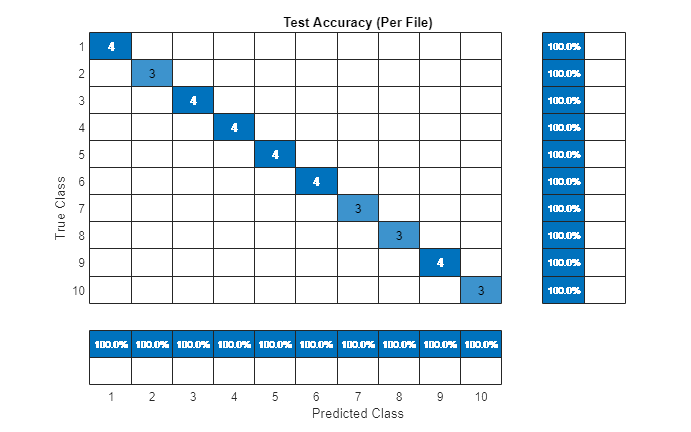

r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(adsTest.Labels,r2,title="Test Accuracy (Per File)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

The predicted speakers match the expected speakers for all files under test.

## References

[1] [Mozilla Common Voice](https://commonvoice.mozilla.org/)

*Copyright 2017-2023 The MathWorks, Inc.*